% Clear workspace and command window
clear;
clc;

% Read data from the Excel file
data = readtable('Rainfall_MM_Loggers_monthly_SUM_April_SWC_NABG.csv');

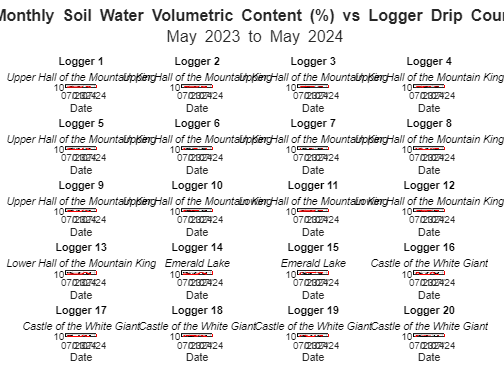


% Extract dates, rainfall, and drip count data
dates = data{:, 1}; %time is in column 1
swc = data{:, 2}; %rainfall is in column 2
drip_count = data{:, 3:22}; % Drip count is in columns 3 to 22

% Predefined titles and subtitles
logger_titles = { 'Logger 1', 'Logger 2', 'Logger 3', 'Logger 4', 'Logger 5', 'Logger 6', 'Logger 7', ... 
    'Logger 8', 'Logger 9', 'Logger 10', 'Logger 11', 'Logger 12', 'Logger 13', 'Logger 14', ...
    'Logger 15', 'Logger 16', 'Logger 17', 'Logger 18', 'Logger 19', 'Logger 20'};

subtitles = {
    'Upper Hall of the Mountain King', 'Upper Hall of the Mountain King', 'Upper Hall of the Mountain King', ...
    'Upper Hall of the Mountain King', 'Upper Hall of the Mountain King', 'Upper Hall of the Mountain King', ...
    'Upper Hall of the Mountain King', 'Upper Hall of the Mountain King', 'Upper Hall of the Mountain King', ...
    'Upper Hall of the Mountain King', 'Lower Hall of the Mountain King', 'Lower Hall of the Mountain King', ...
    'Lower Hall of the Mountain King', 'Emerald Lake', 'Emerald Lake',  'Castle of the White Giant'...
    'Castle of the White Giant', 'Castle of the White Giant', 'Castle of the White Giant', 'Castle of the White Giant'...
};

% Create a figure with 20 subplots
figure; clf
tiledlayout(5, 4, 'TileSpacing', 'tight');

% Loop through loggers to plot data
for i = 1:20
    nexttile
    yyaxis left;
    plot(dates, swc, 'k'); % Plot SWC data
    ylabel('SWVC 10cm (%)', 'Color', 'b');
    
    yyaxis right;
    plot(dates, drip_count(:, i), 'r'); % Plot Drip Count for the ith logger
    xlabel('Date');
    ylabel('Drip Count', 'Color', 'r');
    
    title(logger_titles{i}, 'FontSize', 9);
    datetick('x', 'mm/yy', 'keepticks');
    xtickangle(0);
    grid on;
    axis padded;
    
    subtitle(subtitles{i}, 'FontSize', 2, 'FontAngle', 'italic');
    
    % Adjust the colors of the y-axes
    ax = gca;
    ax.YAxis(1).Color = 'k';
    ax.YAxis(2).Color = 'r';
    ax.YAxis(2).Exponent = 0; % Disable scientific notation for drip count
end

% Add a shared title for the entire figure
sgtitle({'\bfMonthly Soil Water Volumetric Content (%) vs Logger Drip Count', 'May 2023 to May 2024'});